## ** Design of Squirrel cage Induction motor**

Using the given parameters, design a Delta Connected 3 Phase Squirrel Cage Induction Motor and find out the Stator Core Dimensions, Number of Stator Slots and Winding Turns and also draw the Speed Torque Curve

clc;
clear;

Horsepower

hp = 30

hp = 30

Frequency

f = 50

f = 50

Nominal Voltage

Vin = 440

Vin = 440

RPM

N = 960

N = 960

Specific Electrical Loading

ac = 25000

ac = 25000

Specific Magnetic Loading

Bav = 0.46

Bav = 0.4600

Power Factor

pf = 0.87

pf = 0.8700

Full Load Efficiency

E = 84

E = 84

Stator Resistance

r1 = 0.641

r1 = 0.6410

Stator Reactance

x1 = 1.106

x1 = 1.1060

Rotor Resistance

r2 = 0.332

r2 = 0.3320

Rotor Reactance

x2 = 0.464

x2 = 0.4640

Magnetization branch reactance

xm = 26.3

xm = 26.3000

Code:

Po = hp*0.746;
Ns = N/60;
Kws = .955; 
phase = 3; 
eff = E/100;
%rating in kVA
Q = Po/(eff*pf); 
Kw = .9; 
Co = 1.11*pi*pi*Bav*ac*Kw*(10^-3); 
%number of poles
pole = (2*f)/Ns; 
%Q = Co*Ns*D2L
v_phase = Vin / sqrt(3); % Phase voltage
w = 0.10472*N; %Synchronous speed (rad/s)
% Calculate the Thevenin voltage and impedance 
v_th = v_phase * ( xm / sqrt(r1^2 + (x1 + xm)^2) ); 
z_th = ((j*xm) * (r1 + j*x1)) / (r1 + j*(x1 + xm)); 
r_th = real(z_th); 
x_th = imag(z_th); 

Input Power is 

Q

Q = 30.6240

Code:

D2L = Q/(Co*Ns); 
%for good overall design
%L/tow = 1%L*pole/pi*D
D3 = (Q*pole)/(Co*Ns*pi); 
D = D3^(1/3);
L = pi*D/(pole);
%peripheral speed Va
Va = pi*D*Ns; 
phim = Bav*pi*D*L/pole; 
Ts = Vin/(4.44*f*phim*Kws);
Ss = 3*pole*phase;
Yss = pi*D/Ss; 
Zss = 6*round(Ts);
nslots = Zss/Ss;
s = (0:1:50) / 50; % Slip
s(1) = 0.001; 
nm = (1 - s) * N; % Mechanical speed % Calculate torque for original rotor resistance 
for ii = 1:51 
 t_ind1(ii) = (3 * v_th^2 * r2 / s(ii))/(w * ((r_th + r2/s(ii))^2 + (x_th + x2)^2) ); 
end
% Calculate torque for doubled rotor resistance
for ii = 1:51 
 t_ind2(ii) = (3 * v_th^2 * (2*r2) / s(ii)) / (w * ((r_th +(2*r2)/s(ii))^2 + (x_th + x2)^2) ); 
end

Diameter is 

D

D = 0.3226

Lenght is

L

L = 0.1622

Peripheral Speed

Va

Va = 16.2171

Permissible Dimension Check

if(Va<30) 
fprintf('\nAs Peripheral speed is less than 30m/secs so dimensions are permissable'); 
else
fprintf('\nAs Peripheral speed is not less than 30m/sec the dimensions are not mpermissabel. But still the dimensions will be'); 
end


As Peripheral speed is less than 30m/secs so dimensions are permissable

Flux Density

phim

phim = 0.0121

Number of Stator Turns

round(Ts)

ans = 172

Number of Stator Slots per phase per pole

Ss

Ss = 56.2500

Slot pitch

Yss

Yss = 0.0180

Number of Conductors

Zss

Zss = 1032

Number of Slots

nslots

nslots = 18.3467

Plot the torque-speed curve

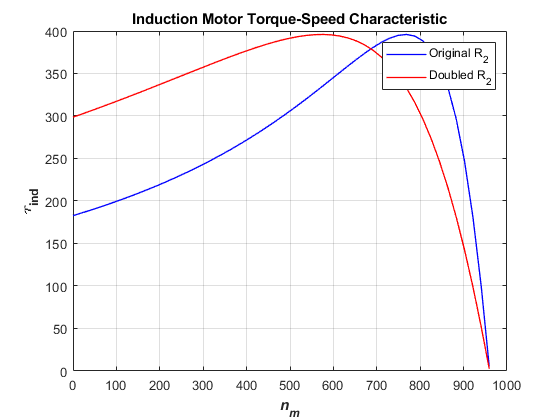

plot(nm,t_ind1,'Color','b','LineWidth',1); 
hold on; 
plot(nm,t_ind2,'Color','r','LineWidth',1); 
xlabel('\itn_{m}','Fontweight','Bold'); 
ylabel('\tau_{ind}','Fontweight','Bold'); 
title ('Induction Motor Torque-Speed Characteristic'); 
legend ('Original R_{2}','Doubled R_{2}'); 
grid on; 
hold off;